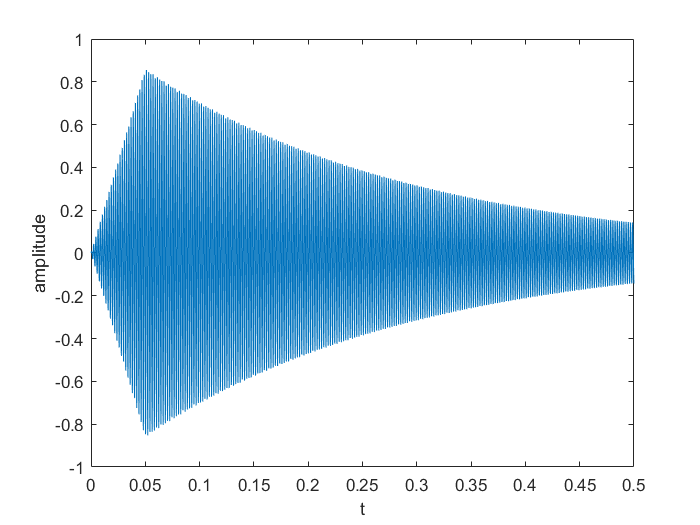

clc;clear;close;
fs=8192;
T=1/2;
scale=2;
wave1=gen_wave(6,scale,0,0,T,fs);
t=linspace(0,T,fs*T);
figure(1);
plot(t,wave1);
xlabel('t');ylabel('amplitude');

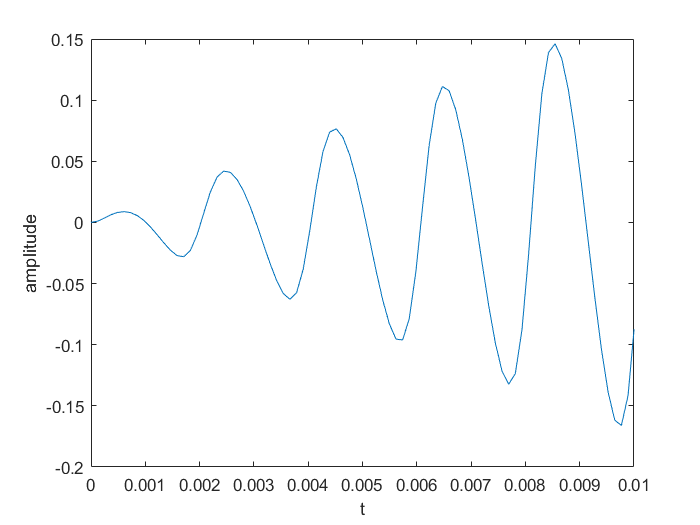

figure(2);
plot(t,wave1);
xlim([0,0.01]);
xlabel('t');ylabel('amplitude');

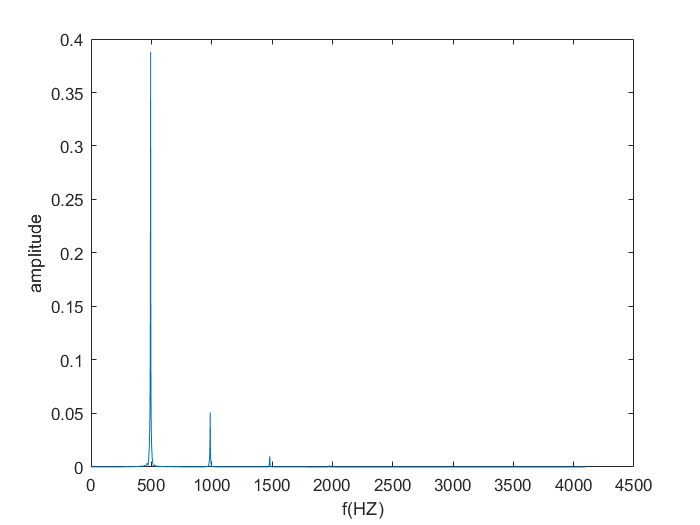

figure(3);
N=length(wave1);
WAVE1=fft(wave1);
magni=abs(WAVE1(1:N/2))*2/N;
f=(0:N/2-1)'*fs/N;

plot(f,magni);
xlabel('f(HZ)');ylabel('amplitude');